# Algoritmos Numéricos por Computadora

# Examen final - Primavera 2022

**Sube tu archivo resultado a Canvas antes de las 18:45 horas.**

Cada pregunta vale 5 puntos.

Los exámenes son trabajos individuales. Está estrictamente prohibido dar o recibir ayuda de cualquier persona. El artículo 29 del Reglamento de Alumnos establece que "se calificará como no acreditada (N.A.) cualquier materia cuando el alumno incurra en alguna práctica fraudulenta".

**Tu script debe desplegar todas las respuestas.**

## 1. Utilizar un lenguaje de programación matricial de manera eficiente.

1.1 En los métodos multipasos para resolver ecuaciones diferenciales ordinarias se utilizan los últimos* k* valores calculados de la función para determinar el valor de la variable en el siguiente punto. Para no guardar todos los valores calculados de la función, puede usarse una cola de tamaño k.  

De manera eficiente agrega 60 a la siguiente cola (k=4). Tu solución no debe depender del contenido de la cola en el ejemplo.

cola = [40,45,50,55];
% la cola debe quedar [45,50,55,60];
cola(1)=[];
cola = [cola 60]

cola =     45    50    55    60


1.2 A partir de la matriz A 

A = magic(5)

A =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


calcula de la manera más compacta posible:

a) La suma del último renglón de la matriz 

s = sum(A(5,:))

s =     65


b) La mediana de A 

M = median(A,'all')

M =     13


c) Cuántos elementos de A son menores a la mediana

B = A < M

B = 5×5 logical array
   0   0   1   1   0
   0   1   1   0   0
   1   1   0   0   0
   1   1   0   0   1
   1   0   0   1   1


%Elementos de A menores a la mediana
nnz(B)

ans =     12


## 2. Identificar los errores numéricos de las soluciones computacionales.

2.1 La serie infinita


$$f\left(n\right)=\sum_{i=1}^n \frac{1}{i^4 }$$


converge a $\frac{\pi^4 }{90}$ conforme $n$ tiende a infinito. Escribe un programa de precisión sencilla para calcular $f\left(n\right)$ para $n=10000$, calculando primero la suma desde $i=1$ hasta 10000 y después en sentido inverso (desde $i=10000$ hasta 1). En lo dos casos, calcula el error absoluto. 

 real = single(pi^4/90)

real = single
   1.0823232


 suma = single(0)

suma = single
     0


 syms i
 % de ida
 f = symsum(1/i^4,i,1,10000)

$$f = \frac{\pi^{4}}{90}-\frac{\psi^{\prime \prime \prime }(10001)}{6}$$

 %res = 0;
 %for i = 1:10000
     %res = res + 1/i^4;
 %end
 %res = 0;
% for i = 10000:1
     %res = res + 1/i^4;
 %end
 er = real - f

$$er = \frac{\psi^{\prime \prime \prime }(10001)}{6}-\frac{\pi^{4}}{90}+\frac{9079185}{8388608}$$

 % de vuelta
 f = symsum(1/i^4,i,1000,1)

$$f = 0$$

 er = suma - f

$$er = 0$$

Explica claramente por qué la suma ascendente tiene un error y la descendente no.

%Como vimos a principio del semestre la computadora tiene errores de
%truncamiento y redondeo, esto por la manera en que son almacenados los
%datos en ella. La computadora almacena en bits y estos tienen un límite de números que pueden almacenar.
%Durante el curso manejamos 64 bits 
%Al comparar pi^4/90 absoluto
%y una aproximación a pi^4/90 va a marcar un error absoluto 
%La computadora realiza las operaciones en binario, las convierte a decimal
%y así es como las regresa

2.2 Determina el número de términos necesarios para aproximar $\cos \left(0\ldotp 3\pi \right)\;$ a 8 decimales con el uso de la serie de Maclaurin.

$\cos \;x=1-\frac{x^2 }{2!}$+$\frac{x^4 }{4!}$-$\frac{x^6 }{6!}$+$\frac{x^8 }{8!}-\cdots$

cos(0.3*pi)

ans =    0.587785252292473


n = 8; 
x = .3*pi; 
format long 
epsilon_s = (.5*10^(2-n)); 
epsilon = 100; maclaurin(1) = 1; 
i=1; 
while epsilon > epsilon_s 
    i=i+1; 
    maclaurin(i) = maclaurin(i-1) + (-1)^(i-1)*x^(2*(i-1))/factorial(2*(i-1)); 
    epsilon = abs((maclaurin(i)-maclaurin(i-1))/maclaurin(i)); 
end
disp(['Con = ', num2str(i)]);

Con = 6


res(1) = 1 - x^2/2+x^4/factorial(4) - x^6/factorial(6) + x^8/factorial(8) - x^10/factorial(10) + x^12/factorial(12) - x^14/factorial(14);

res(1)

ans =    0.587785252292455


## 3. Solucionar de manera numérica ecuaciones diferenciales.

Se lanza un proyectil hacia arriba desde la superficie de la Tierra con una velocidad inicial de 1500 m/s. Se acepta que la única fuerza que actúa sobre el objeto es la fuerza debida a la gravedad hacia abajo. En estas condiciones, se usa un balance de fuerzas para obtener:


$$\frac{\mathrm{d}}{\mathrm{d}t}v=-g\frac{R^2 }{{\left(R+x\right)}^2 }$$


donde $v$ es la velocidad hacia arriba (m/s), $x$ es la altitud (m) medida hacia arriba a partir de la superficie terrestre y *R* es el radio de la Tierra. 

Grafica (solo) la altura $x$ del proyectil en los primeros 250s de vuelo. Utiliza el método rk4 y h=0.1.

R = 6.37e6;
g = 9.81;
x = 250;
dv = @(t,x) -g*(R^2/(R + x)^2)

dv = function_handle with value:
    @(t,x)-g*(R^2/(R+x)^2)


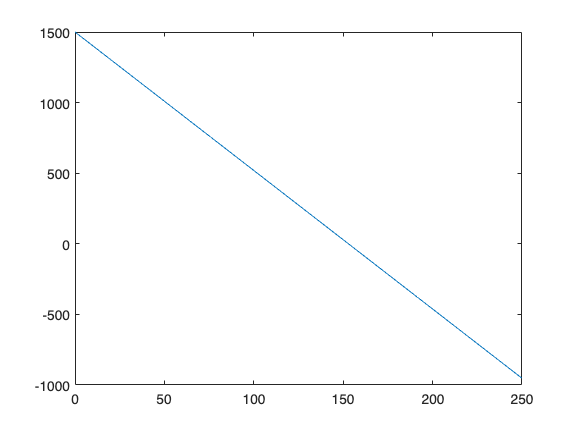

[t,x] = odeRK4(dv,1500,0,250,0.1);
plot(t,x)

Calcula la máxima altura que alcanza el proyectil (usando los valores de *x* calculados antes) y en cuánto tiempo la alcanza?

y = 250;
f = @(t,y) (-9.81*((63.37*10^6)^2)/(6.37*10^6 + y)^2);
y0 = 1500;
[t,y] = odeRK4(f, y0, 0, 2, 0.1);
plot(t,y);
xlabel('t');
legend('y1', 'y2','location', 'best');

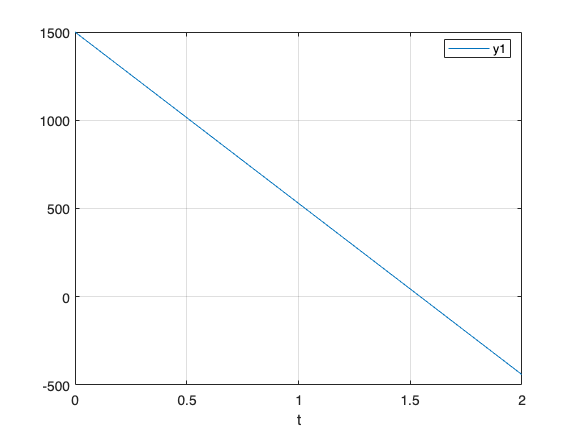

grid on;

## 4. Familiarizarse con el modelado matemático de sistemas físicos.

Un péndulo amortiguado pierde energía y, a partir de cualquier condición inicial, termina en la posición vertical de reposo. La fuerza amortiguamiento, friction, se modela frecuentemente como proporcional y en el sentido opuesto a la velocidad. La ecuación del péndulo queda entonces como

 
$$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }\theta +\mu \frac{d}{\mathrm{d}t}\theta +\frac{g}{l}\;\theta =0$$


donde $\mu >0$ es el coeficiente de amortiguamiento.

Grafica (solo) la posición $\theta$ del péndulo en función del tiempo durante 20s. La posición inicial es $\theta_0 =\frac{\pi }{8}$ y la velocidad inicial es cero.

g = 9.81;
l = 1;
miu = 0.25;
theta=pi/8;
M= [0,1,1; -1,-miu,-g/l]

M =                    0   1.000000000000000   1.000000000000000
  -1.000000000000000  -0.250000000000000  -9.810000000000000


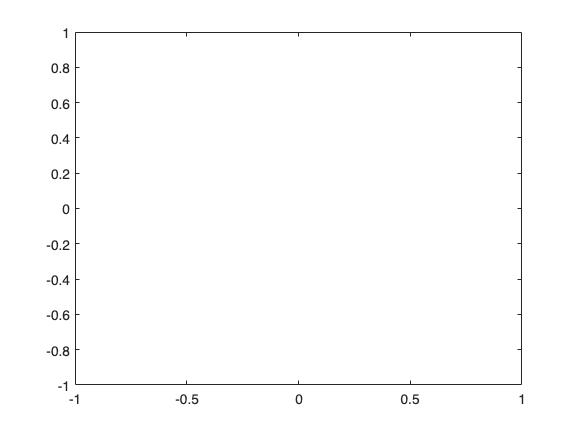

b= [0;0;0];
f1=@(t,y) M*thetha + b;
y0=[0;0;0];
t0=0;
h=0.1;
tf=20;
[t,y] =odeEuler(f1,t0,y0,h,tf);
plot(t,y);

A partir de los valores propios de la matriz que describe el sistema, determina ¿cuál es el período (en *s*) de la parte oscilatoria de la respuesta? 

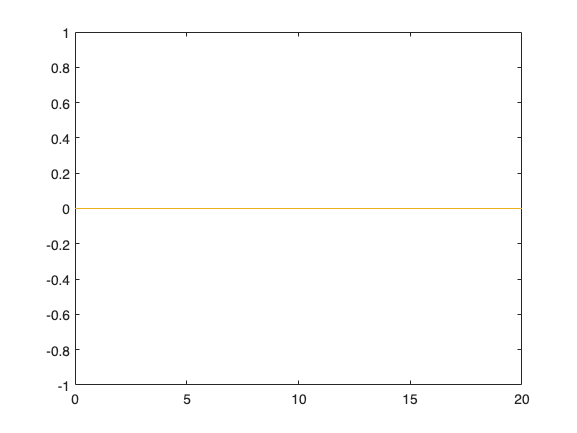

f=@(t,th) [th(2);miu*th(1);-(g/l)*th(1)];
t0=0;
tf=20;
h=0.1;
[t,y]=odeRK4bis(f,y0,t0,tf,h);
plot(t,y)

¿Cuál es la constante de decaimiento (en $s^{-1}$) de la envolvente exponencial?

## 5. Entender el funcionamiento de diversos métodos numéricos.

Resuelve la ecuación 


$$\frac{{\mathrm{d}}^3 }{\mathrm{d}t^3 }x+x=0$$


con las condiciones iniciales $x^{\prime \prime } \left(0\right)=0,{\;x}^{\prime } \left(0\right)=1,\;x\left(0\right)=0$.

Grafica x(t) en el intervalo [0 , 10] .

Solución simbólica

syms x(t)
eqn = diff(x, 3) + x == 0

$$eqn(t) = \frac{\partial^{3}}{\partial t^{3}}x\left(t\right)+x\left(t\right)=0$$

cond = [x(0) == 0, x(1) == 1, x(2) == 0];
sol = dsolve(eqn, cond)

$$sol = \begin{array}{l} \frac{{\mathrm{e}}^{-t}\,{\mathrm{e}}^{-\frac{1}{2}}\,\left(\sigma_{1}\,\sin\left(\sigma_{2}\right)-{\mathrm{e}}^{3}\,\sin\left(\sqrt{3}\right)+\sigma_{1}\,{\mathrm{e}}^{3}\,\cos\left(\sigma_{2}\right)\,\sin\left(\sqrt{3}\right)-\sigma_{1}\,{\mathrm{e}}^{3}\,\sin\left(\sigma_{2}\right)\,\cos\left(\sqrt{3}\right)\right)}{\sigma_{3}-{\mathrm{e}}^{3/2}\,\sin\left(\sqrt{3}\right)+\cos\left(\frac{\sqrt{3}}{2}\right)\,{\mathrm{e}}^{3}\,\sin\left(\sqrt{3}\right)-\sigma_{3}\,{\mathrm{e}}^{3}\,\cos\left(\sqrt{3}\right)}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{\frac{3\,t}{2}}\\ \sigma_{2}=\frac{\sqrt{3}\,t}{2}\\ \sigma_{3}=\sin\left(\frac{\sqrt{3}}{2}\right) \end{array}$$

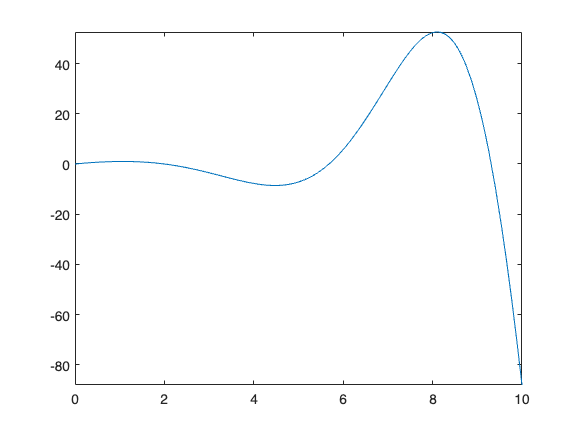

fplot(sol, [0, 10])

Solución numérica

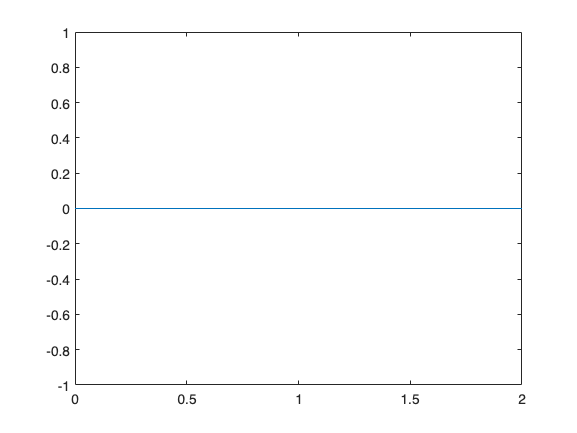

a=0;
b=1;
c=2;
ya=0;
yb=1;
yc=0;
n = 1000;
[t, y] = odeDiffsFinitasTD(a, c, ya, yc, n);
plot(t,y)

function [t,y]=odeRK4(f,y0,t0,tf,h)
    t=t0:h:tf;
    n=length(t);
    m=length(y0);
    y=zeros(m,n);
    y(:,1)=y0;
    for i=1:n-1
        k1=f(t(i),y(:,i));
        k2=f(t(i)+0.5*h,y(:,i)+0.5*k1*h);
        k3=f(t(i)+0.5*h,y(:,i)+0.5*k2*h);
        k4=f(t(i)+h,y(:,i)+k3*h);
        phi=(k1+2*k2+2*k3+k4)/6;
        y(:,i+1)=y(:,i)+phi*h;
    end
end

function [t, y] = odeDiffsFinitasTD(a, b, ya, yb, n)
    h = (b - a)/(n - 1);

    e=-1*ones(1,n);
    f=2*ones(1,n);
    g=-1*ones(1,n);

    c=4*h^2;
    C=c*ones(1,n);
    f=f+C;

    r=zeros(n,1);
    r(1)=ya;
    r(end)=yb;

    t=a:h:b;
    y = Tridiag(e, f, g, r);
end

function x = Tridiag(e,f,g,r)
    n=length(f);
    for k = 2:n
        factor = e(k)/f(k-1);
        f(k) = f(k) - factor*g(k-1);
        r(k) = r(k) - factor*r(k-1);
    end
    x=zeros(n,1);
    x(n) = r(n)/f(n);
    for k = n-1:-1:1
        x(k) = (r(k)-g(k)*x(k+1))/f(k);
    end
end

function [t,y]=odeEuler(f,y0,t0,tf,h)
    t=t0:h:tf;
    y = zeros(size(t));
    n=length(t);
    y(1)=y0;
    for i=1:1:n-1
       phi=f(t(i),y(i));
       y(i+1)=y(i)+h*phi;
    end
end

function [t,y] =odeRK4bis(f,y0,t0,tf,h)
    t=t0:h:tf;
    n=length(t);
    m=length(y0);
    y=zeros(m,n);
    y(:,1)=y0;
    for i=1:n-1
        k1=f(t(i),y(:,i));
        k2=f(t(i)+0.5*h,y(:,i)+0.5*k1*h);
        k3=f(t(i)+0.5*h,y(:,i)+0.5*k2*h);
        k4=f(t(i)+h,y(:,i)+k3*h);
        phi=(k1+2*k2+2*k3+k4)/6;
        y(:,i+1)=y(:,i)+phi*h;
    end
end
